# Pupil

Pupil-to-limbus ratio ranged from 0.15 to 0.73 in the dataset analyzed by Ortiz et al. 2013

clearvars
orientation = "OD";
data = [982.7907609939575, 1969.9149737358093;... % LLO coordinates
    1028.097038269043, 1972.8139972686768;...
    979.7043585777283, 2014.1077580451965;...
    936.1634683609009, 1967.3229608535767;...
    985.705623626709, 1926.440020084381;...
    1439.1738414764404, 1966.8851761817932;...
    1393.0528020858765, 1964.782208442688;...
    1436.9346284866333, 2010.455840587616;...
    1486.072998046875, 1969.5023131370544;...
    1441.3345098495483, 1924.342758178711];
P0 = data(1,:);
P2 = data(6,:);
I = imread("IMG_0453.JPG");
I = fliplr(permute(I,[2 1 3]));
h = size(I,1);

Crop out region about the pupil roughly double the size of cornea

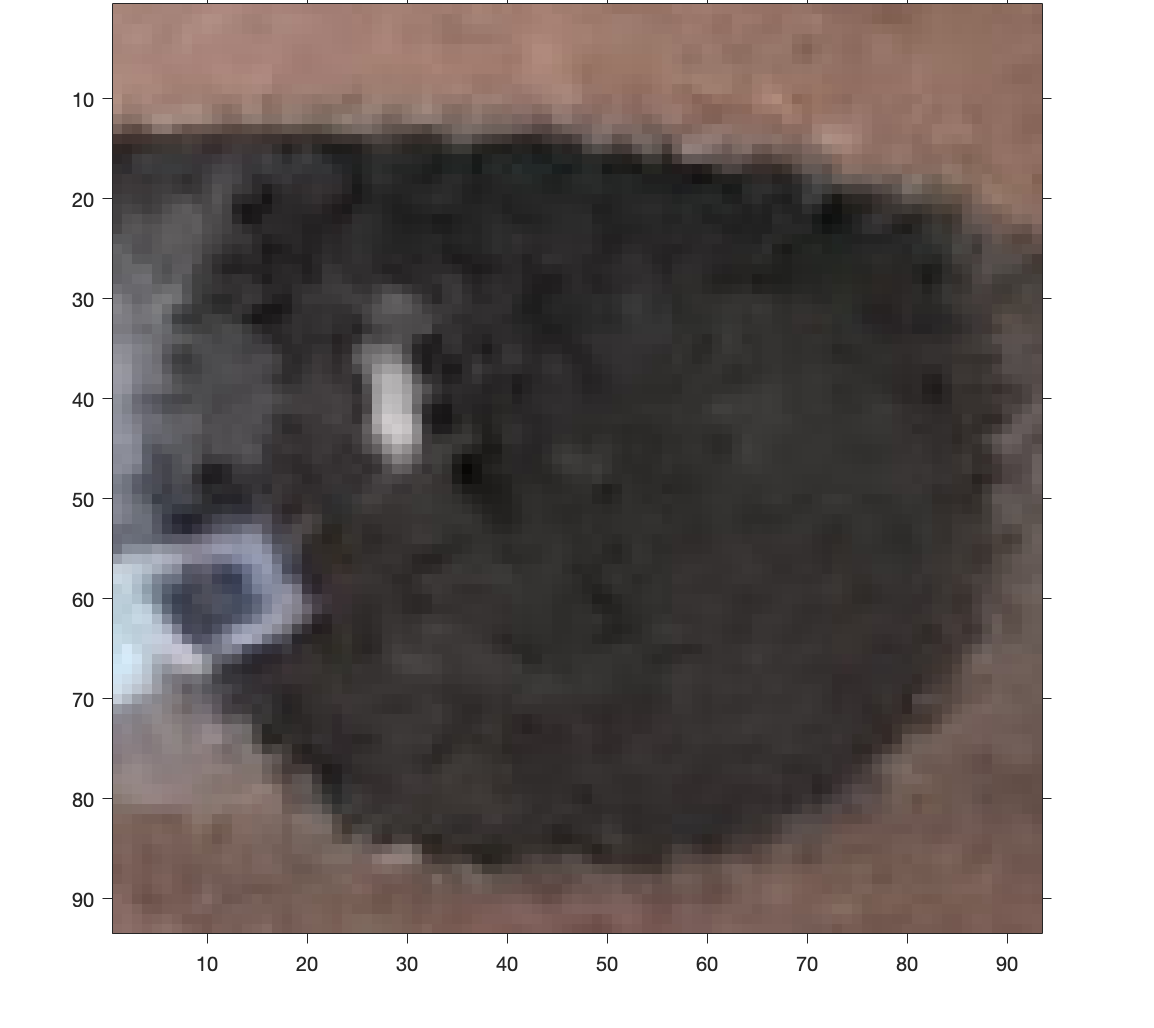

R0 = sqrt(sum((data(2,:) - data(4,:)).^2));
C0 = [P0(1), h - P0(2)];
rect0 = [C0 - 0.5*R0, R0,R0];
E0 = imcrop(I, rect0);
imshow(E0, 'InitialMagnification', 1000)

% hold on
% 
% t = 1:360;




## References

Ortiz, Estefan, Kevin W. Bowyer, and Patrick J. Flynn. "A linear regression analysis of the effects of age related pupil dilation change in iris biometrics." *2013 IEEE Sixth International Conference on Biometrics: Theory, Applications and Systems (BTAS)*. IEEE, 2013.